# Train Self-Balancing Bicycle Using Reinforcement Learning Agents

Load the parameters of the model into the MATLAB® workspace.

config

Open Simulink Model

model = 'SimpleBikeRlAgentControl';
open_system(model)

## **Create Environment Interface**

Create the observation specification.

numObs = 15;
obsInfo = rlNumericSpec([numObs 1]);
obsInfo.Name = "observations";

Create the action specification.

numAct = 1;
actInfo = rlNumericSpec([numAct 1],LowerLimit=-1,UpperLimit=1);
actInfo.Name = "actions";

Create the environment interface for the walking robot model.

blk = model + "/RL Agent";
env = rlSimulinkEnv(model,blk,obsInfo,actInfo);
env.ResetFcn = @(in) SimplebikeResetFcn(in, ...
    path_n_points, ...
    path_max_dim, ...
    cvx_hull_n_points ...
    );

## Create Agent for Training

Build the Critic Network

criticLayerSizes = [400 300];

statePath = [
    featureInputLayer(numObs,'Normalization','none','Name', 'observation')
    fullyConnectedLayer(criticLayerSizes(1), 'Name', 'CriticStateFC1', ... 
            'Weights',2/sqrt(numObs)*(rand(criticLayerSizes(1),numObs)-0.5), ...
            'Bias',2/sqrt(numObs)*(rand(criticLayerSizes(1),1)-0.5))
    reluLayer('Name','CriticStateRelu1')
    fullyConnectedLayer(criticLayerSizes(2), 'Name', 'CriticStateFC2', ...
            'Weights',2/sqrt(criticLayerSizes(1))*(rand(criticLayerSizes(2),criticLayerSizes(1))-0.5), ... 
            'Bias',2/sqrt(criticLayerSizes(1))*(rand(criticLayerSizes(2),1)-0.5))
    ];
actionPath = [
    featureInputLayer(numAct,'Normalization','none', 'Name', 'action')
    fullyConnectedLayer(criticLayerSizes(2), 'Name', 'CriticActionFC1', ...
            'Weights',2/sqrt(numAct)*(rand(criticLayerSizes(2),numAct)-0.5), ... 
            'Bias',2/sqrt(numAct)*(rand(criticLayerSizes(2),1)-0.5))
    ];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(1, 'Name', 'CriticOutput',...
            'Weights',2*5e-3*(rand(1,criticLayerSizes(2))-0.5), ...
            'Bias',2*5e-3*(rand(1,1)-0.5))
    ];

% Connect the layer graph
criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork, actionPath);
criticNetwork = addLayers(criticNetwork, commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

Build the Actor Network

actorLayerSizes = [400 300];
actorNetwork = [
    featureInputLayer(numObs,'Normalization','none','Name','observation')
    fullyConnectedLayer(actorLayerSizes(1), 'Name', 'ActorFC1', ...
            'Weights',2/sqrt(numObs)*(rand(actorLayerSizes(1),numObs)-0.5), ... 
            'Bias',2/sqrt(numObs)*(rand(actorLayerSizes(1),1)-0.5))
    reluLayer('Name', 'ActorRelu1')
    fullyConnectedLayer(actorLayerSizes(2), 'Name', 'ActorFC2', ... 
            'Weights',2/sqrt(actorLayerSizes(1))*(rand(actorLayerSizes(2),actorLayerSizes(1))-0.5), ... 
            'Bias',2/sqrt(actorLayerSizes(1))*(rand(actorLayerSizes(2),1)-0.5))
    reluLayer('Name', 'ActorRelu2')
    fullyConnectedLayer(numAct, 'Name', 'ActorFC3', ... 
                       'Weights',2*5e-3*(rand(numAct,actorLayerSizes(2))-0.5), ... 
                       'Bias',2*5e-3*(rand(numAct,1)-0.5))                       
    tanhLayer('Name','ActorTanh1')
    ];

Set Hyperparams

%% Specify options for the critic and actor representations using rlOptimizerOptions
criticOptions = rlOptimizerOptions('Optimizer','adam','LearnRate',1e-3,... 
                                        'GradientThreshold',1,'L2RegularizationFactor',2e-4);
actorOptions = rlOptimizerOptions('Optimizer','adam','LearnRate',1e-3,...
                                       'GradientThreshold',1,'L2RegularizationFactor',1e-5);

%% Create critic and actor representations using specified networks and
% options
critic = rlQValueFunction(criticNetwork,obsInfo,actInfo,'ObservationInputNames','observation','ActionInputNames','action');
actor  = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

%% Specify DDPG agent options
agentOptions = rlDDPGAgentOptions;
agentOptions.SampleTime = Ts;
agentOptions.DiscountFactor = DiscountFactor;
agentOptions.MiniBatchSize = MiniBatchSize;
agentOptions.ExperienceBufferLength = 1e6;
agentOptions.TargetSmoothFactor = 5e-3;
% agentOptions.NoiseOptions.MeanAttractionConstant = 1;
% agentOptions.NoiseOptions.Variance = 0.1;
agentOptions.ActorOptimizerOptions = actorOptions;
agentOptions.CriticOptimizerOptions = criticOptions;

%% Create agent using specified actor representation, critic representation and agent options
agent = rlDDPGAgent(actor,critic,agentOptions);

## Specify Training Options

maxEpisodes = trainingMaxEpisodes;
maxSteps = floor(Tf/Ts);
trainOpts = rlTrainingOptions(...
    MaxEpisodes=maxEpisodes,...
    MaxStepsPerEpisode=maxSteps,...
    ScoreAveragingWindowLength=250,...
    Verbose=false,...
    Plots="training-progress",...
    StopTrainingCriteria="EpisodeCount",...
    StopTrainingValue=maxEpisodes,...
    SaveAgentCriteria="EpisodeFrequency",...
    SaveAgentValue=500, ...
    SaveAgentDirectory = pwd + "\CandidateAgents");

To train the agent in parallel, specify the following training options. Training in parallel requires Parallel Computing Toolbox™. If you do not have Parallel Computing Toolbox software installed, set `UseParallel` to `false`.

- Set the `UseParallel` option to t`rue`.

- Train the agent in parallel asynchronously.

- After every 32 steps, have each worker send experiences to the parallel pool client (the MATLAB® process which starts the training). DDPG and TD3 agents require workers to send experiences to the client.

trainOpts.UseParallel = false;
% trainOpts.ParallelizationOptions.Mode = "async";
% trainOpts.ParallelizationOptions.StepsUntilDataIsSent = 32;
% trainOpts.ParallelizationOptions.DataToSendFromWorkers = "Experiences";

## Train Agent

Turn on the visualization of the environment during training

USE_PRE_TRAINED_MODEL = false;

% Set agent option parameter:
agentOpts.ResetExperienceBufferBeforeTraining = not(USE_PRE_TRAINED_MODEL);

set_param(model,'SimMechanicsOpenEditorOnUpdate','off');

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. This process is computationally intensive and takes several hours to complete for each agent. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining `to `true`. Due to randomness in the parallel training, you can expect different training results from the plots that follow. The pretrained agents were trained in parallel using four workers.

doTraining = true;
if doTraining
    % Train the agent.8im
    trainingStats = train(agent,env,trainOpts);
end

## Simulate Trained Agents

Load trained model

set_param(model,'SimMechanicsOpenEditorOnUpdate','on');
load("CandidateAgents/Agent500.mat","agent")

Fix the random generator seed for reproducibility.

rng(10)

To validate the performance of the trained agent, simulate it within the biped robot environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

simOptions = rlSimulationOptions(MaxSteps=5*maxSteps);
experience = sim(env,agent,simOptions);

Found algebraic loop containing: 
SimpleBikeRlAgentControl/env/Blue Bike/Rear Wheel/Tyre model/Camber thrust/Dot Product1
SimpleBikeRlAgentControl/env/Blue Bike/Rear Wheel/Tyre model/Camber thrust/Trigonometric Function
SimpleBikeRlAgentControl/env/Config/Solver Configuration/EVAL_KEY/INPUT_4_1_1
SimpleBikeRlAgentControl/env/Config/Solver Configuration/EVAL_KEY/STATE_1


Plot the bike trajectory as well as the reference path.

bike_x = getElement(experience.SimulationInfo.yout, "bike_x").Values.Data

bike_x =    -0.0000
    0.0001
    0.0007
    0.0038
    0.0102
    0.0164
    0.0220
    0.0277
    0.0331
    0.0381


bike_y = getElement(experience.SimulationInfo.yout, "bike_y").Values.Data

bike_y =     0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000



path_x = getElement(experience.SimulationInfo.yout, "path_x").Values.Data

path_x =          0    4.6821    9.9832   15.9876   22.6289   29.7250   37.0906   44.5405   51.8896   58.9525   65.5441   71.4792   76.5726   80.6391   83.4934   84.9504   84.8248   82.9314   79.0851   73.1006   64.7928   53.9763   40.4660   40.4660   23.7364    9.1930   -3.2911  -13.8428  -22.5888  -29.6561  -35.1715  -39.2619  -42.0541  -43.6749  -44.2513  -43.9100  -42.7780  -40.9821  -38.6491  -35.9059  -32.8794  -29.6963  -26.4837  -23.3659  -20.3757  -17.4268  -14.4248  -11.2755   -7.8845   -4.1574


path_y = getElement(experience.SimulationInfo.yout, "path_y").Values.Data

path_y =          0   -0.1698   -0.0000    0.4994    1.3321    2.5123    4.0544    5.9727    8.2818   10.9961   14.1299   17.6978   21.7141   26.1932   31.1497   36.5978   42.5522   49.0270   56.0369   63.5963   71.7194   80.4209   89.7150   89.7150   88.3267   86.3421   83.8164   80.8049   77.3629   73.5454   69.4078   65.0053   60.3930   55.6263   50.7602   45.8502   40.9513   36.1187   31.4078   26.8738   22.5718   18.5570   14.8848   11.6096    8.7585    6.3230    4.2923    2.6555    1.4018    0.5202


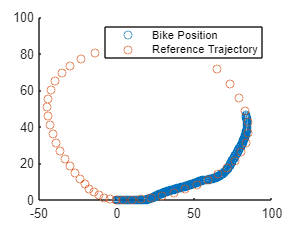


scatter(bike_x, bike_y)
hold on

scatter(path_x, path_y)
legend("Bike Position", "Reference Trajectory")
hold off

save("CandidateAgents\FinalAgent.mat", "agent")